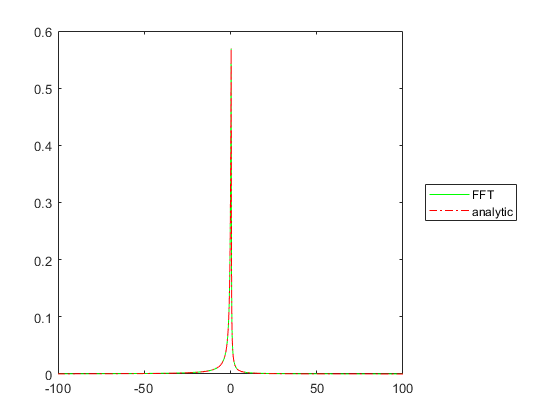

format long
N=2^20;
xc=200;
wc=0 ;
dk=1/(2*xc);
dx=(2*xc)/N  ;
e=0.5;
a=0.5;
b=-0.5;  
s=1;
m=0;
f=frft(alphachar(a,b,s,m,xc,wc,N),e);
%% the x-axis values
F=zeros(N,1);
for i  = 1 : N
 F(i)=wc+e*((i-1)*dx-xc);
end
%%
pd = makedist('Stable','alpha',a,'beta',b,'gam',s,'delta',m);
y=pdf(pd,F);
 plot(F,f,'g-');
hold on
plot(F,y,'r-.');
legend('FFT','analytic','Location','eastoutside')
hold off

ffinal=[F,f,y];